**Top Level Summary:**


$$\begin{array}{l}
\delta h\left(x\right)=h_{\textrm{numerical}} -h_{\textrm{exact}} \;\textrm{is}\;\textrm{plotted}\;\\
h_{\textrm{exact}} \left(x\right)=\left\lbrace \begin{array}{cc}
\frac{\sin \left(x\right)}{x} & x\not= 0\\
1 & x=0
\end{array}\right.
\end{array}$$


**Working and Implementation Summary:**

$h_{\textrm{numerical}}$ was calculated in 3.(c).

Call Q3c to retrieve $h_{\textrm{numerical}}$ and compute the difference between the precise solution, $\frac{1}{x}\sin \left(x\right)$ and our RK4 solution $h_{\textrm{numerical}}$. 

The difference is stored in the variable: h_error, $\delta h\left(x\right)$.

xn = pi;            %Upper Bound
n=100;              %n
x0=0;               %Lower Bound
dx = (xn-x0)/n;     %Increments 
%note to see the 
h_numerical = RKSolver(x0,xn,n, false);

x =      0

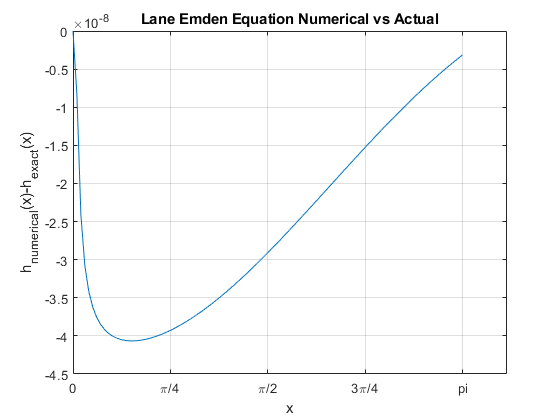

x = linspace(0, xn, length(h_numerical));
h_exact = sin(x)./x;
h_exact(1) = 1;
h_error = h_numerical-h_exact;

plot(x, h_error)
xlabel('x')
ylabel('h_n_u_m_e_r_i_c_a_l(x)-h_e_x_a_c_t(x)')
grid on    
xlabel('x')
xticks([0, pi/4, pi/2, 3*pi/4 pi])
xticklabels({'0','\pi/4','\pi/2','3\pi/4','pi'})
title('Lane Emden Equation Numerical vs Actual')


    %we label the y axis with our equation name
